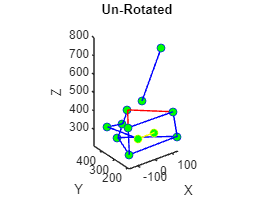

%function [Knuckle,Strut] = Lotus_AARM(z,ChassiHP,KnuckleHP,StrutIn)

%Chassi HPs include the points in order [[upper forward];[upper
%rear];[lower forward];[lower rear]]

%Knuckle HPs include points in order [[upper Knuckle point];[Lower knuckle
%Point]];

%Strut Points are [[Upper mounting point];[lower mounting point]];

%TieRod points are [[Rack end]; [Knuckle end]];

%  -158.35 236.32 249.21 POINT ( 1 ) = Lower wishbone front pivot
%  141.65 236.32 275.34 POINT ( 2 ) = Lower wishbone rear pivot
%  -7.55 462.26 214.17 POINT ( 3 ) = Lower wishbone outer ball joint
%  -143.14 240.51 354.97 POINT ( 5 ) = Upper wishbone front pivot
%  156.86 240.55 363.68 POINT ( 6 ) = Upper wishbone rear pivot
%  7.55 437.74 319.23 POINT ( 7 ) = Upper wishbone outer ball joint
%  4145.00 575.00 475.00 POINT ( 8 ) = Damper wishbone end
%  4180.00 405.00 800.00 POINT ( 9 ) = Damper body end
%  -109.50 488.52 260.28 POINT ( 11 ) = Outer track rod ball joint
%  -103.61 186.32 323.15 POINT ( 12 ) = Inner track rod ball joint
%  4180.00 405.00 800.00 POINT ( 16 ) = Upper spring pivot point
%  4145.00 575.00 475.00 POINT ( 17 ) = Lower spring pivot point
%  0.00 450.00 266.70 POINT ( 18 ) = Wheel spindle point
%  0.00 550.00 266.70 POINT ( 19 ) = Wheel centre point
%  4030.00 440.00 195.00 POINT ( 20 ) = Part 1 C of G
%  4170.00 520.00 450.00 POINT ( 21 ) = Part 2 C of G
%  4230.00 525.00 220.00 POINT ( 22 ) = Part 3 C of G
%  4130.00 720.00 275.00 POINT ( 23 ) = Part 4 C of G


ChassiHP=[[-148.49 200.00 430.09];[ 118.94 200.00 423.05];[-141.45 200.00 280.17];[143.57 200.00 280.17]];
StrutIn=[[50 200 800.00];[11 300 475.00]];
KnuckleHP=[[11.83 412.77 373.28];[-11.95 457.45 210.12]];
TieRodIn=[[-97.76 187.81 357.71];[-69.16 463.46 285.87]];
WheelSpindle=[0.00 435.00 292.10];



Plot_Suspension(ChassiHP,KnuckleHP,StrutIn,TieRodIn,'Un-Rotated','blue')

### **Aligned with -Y to Forward  axis, -X as Right Axis and +Z as Up axis**

This is due to the code configuration.

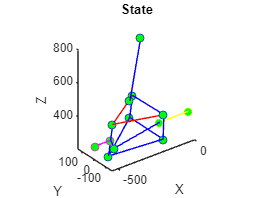

[Rotation,FLIP]=Rotation_FLIP("-x","RIGHT");

ChassiHP=RZ(ChassiHP,Rotation,FLIP);
StrutIn=RZ(StrutIn,Rotation,FLIP);
KnuckleHP=RZ(KnuckleHP,Rotation,FLIP);
TieRodIn=RZ(TieRodIn,Rotation,FLIP);
WheelSpindle=RZ([0.00 450.00 266.70],180,FLIP); %EDIT

Plot_Suspension(ChassiHP,KnuckleHP,StrutIn,TieRodIn,'State','blue',[(KnuckleHP(1,:)+KnuckleHP(2,:))/2;((KnuckleHP(1,:)+KnuckleHP(2,:))/2 + [-100 0 0])])

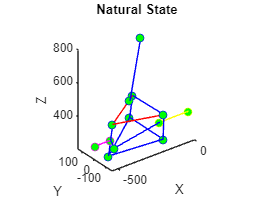

%Natural State
Plot_Suspension(ChassiHP,KnuckleHP,StrutIn,TieRodIn,'Natural State','blue',[(KnuckleHP(1,:)+KnuckleHP(2,:))/2;((KnuckleHP(1,:)+KnuckleHP(2,:))/2 + [-100 0 0])])


z=-100:20:160;

Camber=zeros(length(z),1);
Toe=Camber;
Castor=Camber;
Kingpin=Camber;
StrutLength=Camber;
MotionRatio=Camber;
LowerArmAngle=Camber;
delx=0;

for i=1:length(z)
   [c,t,cs,kp,sl,laa] = OP_Param(ChassiHP,StrutIn,KnuckleHP,TieRodIn,z(i),delx);
   Camber(i)=c;
   Toe(i)=t;
   Castor(i)=cs;
   Kingpin(i)=kp;
   StrutLength(i)=sl;
   LowerArmAngle(i)=laa;
end

MotionRatio(1)=abs((StrutLength(2)-StrutLength(1))/(z(2)-z(1)));
for i=2:(length(z)-1)
    MotionRatio(i)=abs((StrutLength(i+1)-StrutLength(i-1))/(z(i+1)-z(i-1)));
end
MotionRatio(end)=abs((StrutLength(end)-StrutLength(end-1))/(z(end)-z(end-1)));


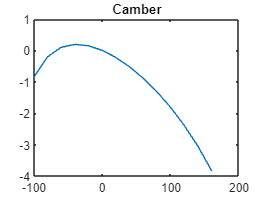


plot(z,Camber)
title('Camber')

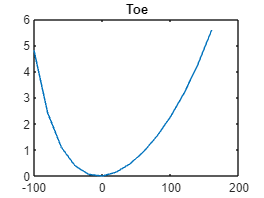


plot(z,Toe)
title('Toe')

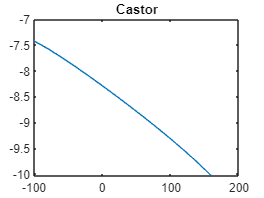


plot(z,Castor)
title('Castor')

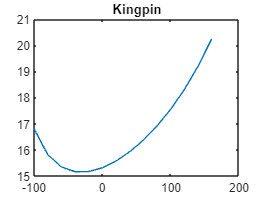


plot(z,Kingpin)
title('Kingpin')

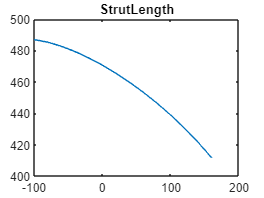


plot(z,StrutLength)
title('StrutLength')

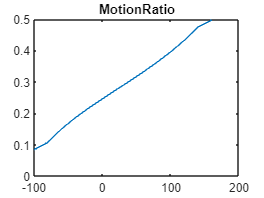


plot(z,MotionRatio)
title('MotionRatio')

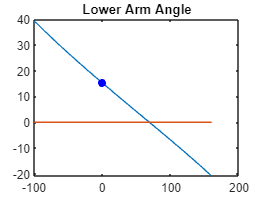


plot(z,LowerArmAngle)
hold on
plot(z,z*0)
scatter(0,interp1(z,LowerArmAngle,0),'ob','filled');
plot(0,interp1(z,LowerArmAngle,0))
hold off
title('Lower Arm Angle')

LowerArmAngle_MAX=max(LowerArmAngle)

LowerArmAngle_MAX = 39.3478

LowerArmAngle_MIN=min(LowerArmAngle)

LowerArmAngle_MIN = -20.8588

LowerArmAngle_BASESTATE=interp1(z,LowerArmAngle,0)

LowerArmAngle_BASESTATE = 15.2212



MotionRatio_Mean=-1*mean(MotionRatio)

MotionRatio_Mean = -0.2897

% [Minimum, At zero Vertical Displacement, Maximum]
[camber,Toe,Castor,KingPIN,StrutLEN,LowerArmAngle,MotionRatioo] = Front_Susp_Parameters(ChassiHP,StrutIn,KnuckleHP,TieRodIn,z,0)

camber =    -3.8340         0    0.1923


Toe =    -0.0000   -0.0000    5.5761


Castor =   -10.0398   -8.2923   -7.4249


KingPIN =    15.1635   15.3145   20.2473


StrutLEN =   411.6035  470.6141  486.9109


LowerArmAngle =   -20.8588   15.2212   39.3478


MotionRatioo =     0.0835    0.2897    0.4969



% 
% Main Code to Calculate Performance
